# FDTD for 2-D TE propagation

# 2A. Monochromatic standing wave (1 hour)

In this second file, we will solve the time evolution of a standing plane wave with wavenumber directed along $x$ inside the same rectangular region of the previous file, the rectangle $[0,XL]\times[0,YL]$.

In order to do so, we will replace the initial conditions and the boundary conditions used in the last file. We will

- enforce at the $t=0$ intial time a **standing wave** in the entire region,

- enforce on the borders of the rectangular domain $x=0$ and $x=XL$ the total field of the **standing wave**,

- enforce on the border of the rectangular domain $y=0$ and $y=YL$ a perfect conducting (PEC) condition.

By virtue of the uniqueness theorem, the electromagnetic field in the region fullfilling the conditions 1-3 can only be the plane wave we look for. As said in the last file, this is possible only because we already know the standing wave we want to compute.

close all; clearvars

Let's put in the following empty code boxes the code written in the previous file.

## 1 Definition of fundamental variables

c   = 3d8;            % Light velocity in vacuum
mu0 = 4*pi*1.d-7;     % Vacuum magnetic permeability
eps0= 1.d-9/(36*pi);  % Vacuum dielectric permettivity

f = 10*1d9;           % Plane-wave frequency (10 GHz)
k_unit = [1 0];       % Unit vector for the plane-wave propagation direction
lambda = 3d8/f;       % Wavelength in vacuum

## 2 Definition of the spatio-temporal grid

### 2.1 Definition of the spatio-temporal regions

XL = 25d-3 ;     % Total length of the domain in the x direction (in meters)
x0 = 0 ;     % Left boundary along x
YL = 5d-3 ;      % Total length of the domain in the y direction (in meters)
y0 = 0 ;      % Bottom boundary along y
TL = 0.1d-9;    % Duration of the simulation (in seconds)
t0 = 0;         % Initial time

### 2.2 Definition of the spatio-temporal grid

% Discretization
NX=25;              % number of cells along the x direction
NY=5;               % number of cells along the y direction
T=350;              % number of time intervals
Delta_x=XL/NX;      % Computing the x discretization step
Delta_y=YL/NY;      % Computing the y discretization step
Delta_t=TL/T;       % Computing the t discretization step
% Sampling instants
t_E = (0:T-1)*Delta_t;
t_H =  t_E+Delta_t/2;

% Sampling points of Ex
x_Ex= (0:NX-1)*Delta_x + Delta_x/2;
y_Ex= (0:NY)*Delta_y;
[y_Ex_grid,x_Ex_grid] = meshgrid(y_Ex,x_Ex);

% Sampling points of Ey
x_Ey= (0:NX)*Delta_x;
y_Ey= (0:NY-1)*Delta_y + Delta_y/2;
[y_Ey_grid,x_Ey_grid] = meshgrid(y_Ey,x_Ey);

% Sampling points of Hz
x_Hz= (0:NX-1)*Delta_x + Delta_x/2;
y_Hz= (0:NY-1)*Delta_y + Delta_y/2;
[y_Hz_grid,x_Hz_grid] = meshgrid(y_Hz,x_Hz);

### 2.3 Visualization of the spatial grid

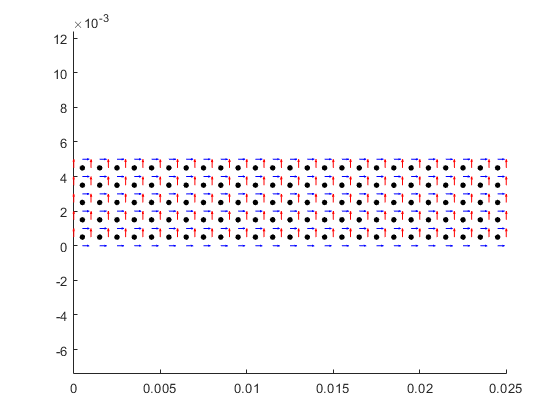

% Grid visualization
figure(1)
scatter( x_Hz_grid(:) , y_Hz_grid(:) ,18,'o','filled','k')
hold on
quiver(x_Ex_grid,y_Ex_grid,ones(size(x_Ex_grid)),zeros(size(y_Ex_grid)),0.1,'b')
hold on
quiver(x_Ey_grid,y_Ey_grid,zeros(size(x_Ey_grid)),ones(size(y_Ey_grid)),0.1,'r')
axis equal

## 4 Control of the stability condition

% Verifying the stability condition
Left= abs(1-2*(c*Delta_t/Delta_x)^2.*sin(k_unit*Delta_x/2));
Right= 1;
Left <= Right;

## 5 Definition of field variables

Let us now inizialize the fields to zero with the "zeros" command.

Each field should be a 2x2 matrix of correct dimensions. Check the dimensions of each component (they are different!) by looking at the dimensions of the matrices of the grids created in Section 3.

Ex= zeros(size(x_Ex_grid));
Ey= zeros(size(x_Ey_grid));
Hz= zeros(size(x_Hz_grid));

## 6 Definition of the initial conditions

Let us enforce the fields at the initial time. As in the previous file, the $E_x$ and $E_y$ components must be enforced at the first E-field instant $(t=0)$. The $H_z$ component must be enforced at the first H-field instant $\left(t=\frac{1}{2}\Delta t\right)$.

Let us write a function "standing_wave.m" which computes the field of a standing plane wave:

    
$$    E_y = \sin\left[k_x (x-XL)\right]\sin\left(2 \pi f t\right) \\
    E_x = 0 \\
    H_z = \frac{1}{120\pi}\cos\left[k_x (x-XL)\right]\cos(2 \pi f t)$$


The input and output variables are already in the code below and in the file of the function.

After defining the initial fields, let us plot them in order to check that the definition is correct. Use the command "pcolor" with the options "set(h, 'EdgeColor', 'none')" and "shading interp". Each field components needs a different plot.

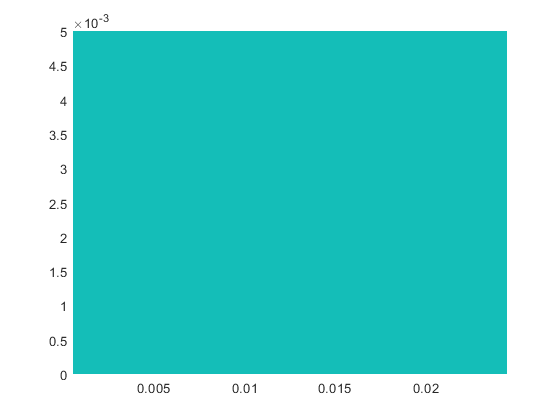

[Ex,Ey,Hz] = standing_wave(x_Ex_grid,y_Ex_grid,x_Ey_grid,y_Ey_grid,x_Hz_grid,y_Hz_grid,t_E(1),t_H(1),f,k_unit,XL);
figure(2)
h=pcolor(x_Ex_grid,y_Ex_grid,Ex);
set(h, 'EdgeColor', 'none');
shading interp

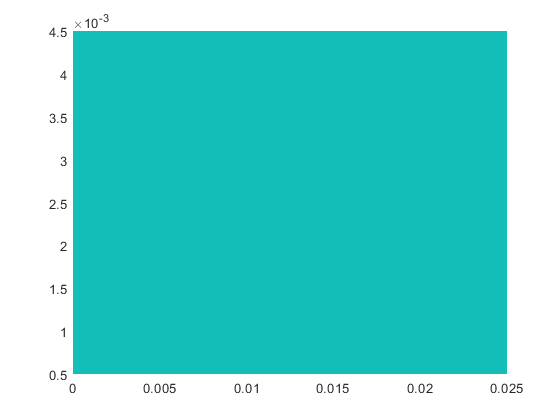

figure(3)
h=pcolor(x_Ey_grid,y_Ey_grid,Ey);
set(h, 'EdgeColor', 'none');

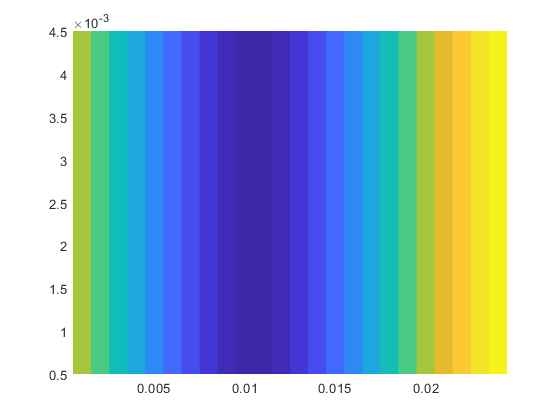

figure(4)
h=pcolor(x_Hz_grid,y_Hz_grid,Hz);
set(h, 'EdgeColor', 'none');

## 7 The FDTD algorithm: the time update

Now let's take the FDTD code used in the previous file and let us modify the boundary condition at $x=0$ with the function "standing_wave". The condition at $x=XL$ is equivalent to a PEC (the $E_y$ field of the standing wave is zero there), so there is no need to explicitly enforce this condition.

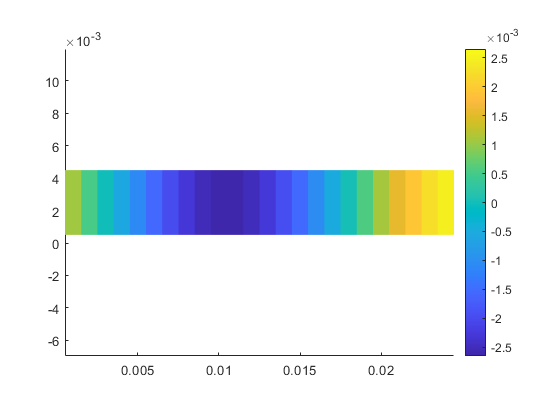

%Definition of the contants for the time update
const_ty_eps = Delta_t/(Delta_y*eps0) ;
const_tx_eps = Delta_t/(Delta_x*eps0) ;
const_ty_mu  = Delta_t/(Delta_y*mu0) ;
const_tx_mu  = Delta_t/(Delta_x*mu0) ;

figure(5)
caxis([-1/(120*pi) 1/(120*pi)])   % Good color scale to plot the Hz field
hold on
set(gcf,'Visible','on')
axis equal
colorbar

for time_instant=1:T
    
    % Boundary conditions on Ea
    
        % 1 Boundary conditions at x=0
        [~,Ey(1,:),~]  = standing_wave(x_Ex_grid,y_Ex_grid,x_Ey_grid(1,:),y_Ey_grid(1,:),x_Hz_grid,y_Hz_grid,t_E(time_instant),t_H(time_instant),f,k_unit,XL);        
        % 2 Travelling-wave boundary conditions at x=XL
        [~,Ey(end,:),~] = standing_wave(x_Ex_grid,y_Ex_grid,x_Ey_grid(end,:),y_Ey_grid(end,:),x_Hz_grid,y_Hz_grid,t_E(time_instant),t_H(time_instant),f,k_unit,XL);    
        
        % 3 PEC boundary conditions at y=0 and at y=YL : no need to update Ex (it stays zero)
     
    
    % E-field time update
        Ey(2:NX,1:NY)=Ey(2:NX,1:NY)-const_tx_eps*(Hz(2:NX,1:NY)-Hz(1:NX-1,1:NY));
    
    
    % H-field time update
        Hz(1:NX,1:NY)=Hz(1:NX,1:NY)-const_tx_mu*(Ey(2:NX+1,1:NY)-Ey(1:NX,1:NY));
        
% Recording the frames for each field


   
    figure(5)
    h= pcolor(x_Hz_grid,y_Hz_grid,Hz);
    set(h, 'EdgeColor', 'none');
    %Hz_frames(time_instant) = getframe;
    
    
end

## 8 Recording the field animation

Record the field computed at all the time instants in the file "Hz_standing_wave.avi". Try to do the same for other field components (but you need to run again the simulation).

% writerObj = VideoWriter('Hz_standing_wave.avi');
% open(writerObj);
% writeVideo(writerObj, Hz_frames)
% close(writerObj);